# File Name: Search_Registration_05_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

## Align Two Point Clouds Using ICP Algorithm

Load point cloud data.

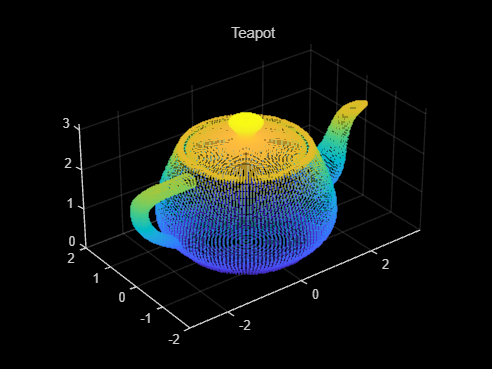

ptCloud = pcread('teapot.ply');

pcshow(ptCloud);
title('Teapot');

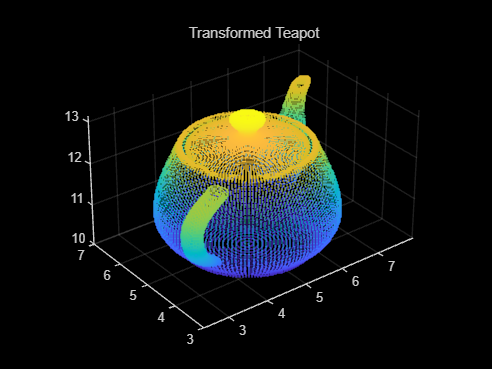


%%%%%%%%%% TODO %%%%%%%%%%
% Create a transform object with 30 degree rotation along z-axis and translation [5,5,10].
A = [cos(pi/6) sin(pi/6) 0 0; ...
    -sin(pi/6) cos(pi/6) 0 0; ...
    0      0 1 0; ...
    5      5 10 1];
tform1 = affine3d(A);

% Transform the point cloud.
ptCloudTformed = pctransform(ptCloud,tform1);

pcshow(ptCloudTformed);
title('Transformed Teapot');


%%%%%%%%%% TODO %%%%%%%%%%
% Apply the rigid registration.
tform = pcregistericp(ptCloudTformed,ptCloud,'Extrapolate',true);


% Compare the result with the true transformation.
disp(tform1.T);

    0.8660    0.5000         0         0
   -0.5000    0.8660         0         0
         0         0    1.0000         0
    5.0000    5.0000   10.0000    1.0000




tform2 = invert(tform);
disp(tform2.T);

    0.8660    0.5000    0.0000         0
   -0.5000    0.8660   -0.0000         0
   -0.0000    0.0000    1.0000         0
    5.0000    5.0000   10.0000    1.0000

